clear; clc; close all;

flyby_id = 'E4';   % options: E4, E14, E19, E26, custom_file

## main loops

% main loops
% define constants & interior structure
r_m = 1560; % Europa radius (km)
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / synodic_period; % synodic freq. (rad/sec)
 
% physical ocean parameters
sigma_ocean = 2.75;  % conductivity (S/m) ~2.5 to 5 S/m for terrestrial seawater
h_ocean     = 150;  % ocean shell thickness (km) estimated to be 100-200km thick from gravity measurements E4
d_ice       = 29;   % ice shell thickness (km)
 
% evaluate Bessel functions to get forward response parameters
[A, phi, M_complex] = calc_europa_induction(sigma_ocean, h_ocean, d_ice, r_m, synodic_period);
 
fprintf('Bessel induction response\n');

Bessel induction response


fprintf('calculated A   : %.4f\n', A);

calculated A   : 0.9453


fprintf('calculated phi : %.4f rad (%.2f deg)\n', phi, rad2deg(phi));

calculated phi : 0.0000 rad (0.00 deg)


 
% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67;  % azimuthal (orbital travel direction)
Bprim_y_amp = 225; % radial (pointing toward Jupiter)
Bprim_z_amp = -410;
 

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
 
% flyby-specific parameters
% each case must define:
%   traj_t    : nx1, seconds elapsed since the start of the encounter
 
%   traj_pos  : nx3, [x y z] spacecraft position in km, in the same
%               coordinate system as the model (x = azimuthal,
%               y = radial toward Jupiter, z = spin axis)
 
%   phi0      : phase offset (rad) that aligns the model's oscillation
%               with the real Jovian field phase at traj_t = 0.
%               
 
 
switch flyby_id
 
  case 'E4'
        data_file = fullfile('flyby data', 'ORB04_EUR_EPHIO.TAB');
        [traj_t, traj_pos, B_meas] = load_galileo_tab(data_file);
        grid_limit = r_m * 7;
 
    case 'E14'
        data_file = fullfile('flyby data', 'ORB14_EUR_EPHIO.TAB');
        [traj_t, traj_pos, B_meas] = load_galileo_tab(data_file);
        grid_limit = r_m * 8.5;
 
 
    case 'E19'
        data_file = fullfile('flyby data', 'ORB19_EUR_EPHIO.TAB');
        [traj_t, traj_pos, B_meas] = load_galileo_tab(data_file);
        grid_limit = r_m * 6.6;
 
    case 'E26'
        data_file = fullfile('flyby data', 'ORB26_EUR_EPHIO.TAB');
        [traj_t, traj_pos, B_meas] = load_galileo_tab(data_file);
        grid_limit = r_m * 13;
 
    case 'custom_file'
        % for any other ephio .tab file with the same column layout as
        % the E4/E14/E16/E26 cases
        data_file = fullfile('flyby data', 'galileo_trajectory.tab');
        [traj_t, traj_pos, B_meas] = load_galileo_tab(data_file);
        grid_limit = r_m * 7;
 
    otherwise
        error('Unknown flyby_id: %s', flyby_id);
end
 
phi0 = 0; % retired
% a phi_x_offset and a phi_y_offest
% are computed below (after loading the trajectory) directly from
% the measured far-field data via an independent least-squares phase fit
% for each component. phi0 is retired.

% phase alignment: independent least-squares fit for phi_x_offset and
% phi_y_offset directly from far-field measured data.

 
R_traj = sqrt(sum(traj_pos.^2, 2));
far_thresh = 3 * r_m; % "far field" = negligible secondary field
far_idx = find(R_traj > far_thresh & ~any(isnan(B_meas(:,1:2)), 2));
 
tt = traj_t(far_idx);
bx = B_meas(far_idx,1);
by = B_meas(far_idx,2);
 
% design matrix for a model of the form P*cos(wt) + Q*sin(wt)
Xd = [cos(omega*tt), sin(omega*tt)];
 
coeff_x = Xd \ bx;   % least-squares solve -> [P; Q] for Bx
coeff_y = Xd \ by;   % least-squares solve -> [P; Q] for By
 
phi_x_offset = atan2(-coeff_x(2), coeff_x(1));
phi_y_offset = atan2(-coeff_y(2), coeff_y(1));



amp_x_fit = sqrt(coeff_x(1)^2 + coeff_x(2)^2);
amp_y_fit = sqrt(coeff_y(1)^2 + coeff_y(2)^2);

fprintf('\nphi_x_offset (fit): %.4f rad (%.2f deg)\n', phi_x_offset, rad2deg(phi_x_offset));


phi_x_offset (fit): 0.5735 rad (32.86 deg)


fprintf('phi_y_offset (fit): %.4f rad (%.2f deg)\n', phi_y_offset, rad2deg(phi_y_offset));

phi_y_offset (fit): 2.2743 rad (130.31 deg)


fprintf('Bx amplitude - assumed: %.1f nT | far-field fit: %.1f nT\n', Bprim_x_amp, amp_x_fit);

Bx amplitude - assumed: 67.0 nT | far-field fit: 81.5 nT


fprintf('By amplitude - assumed: %.1f nT | far-field fit: %.1f nT\n', Bprim_y_amp, amp_y_fit);

By amplitude - assumed: 225.0 nT | far-field fit: 220.9 nT


fprintf('N far-field points used: %d\n', numel(far_idx));

N far-field points used: 4356


fprintf('R (far-field): mean=%.1f km (%.2f r_m), min=%.1f, max=%.1f\n\n', ...
    mean(R_traj(far_idx)), mean(R_traj(far_idx))/r_m, min(R_traj(far_idx)), max(R_traj(far_idx)));

R (far-field): mean=7010.1 km (4.49 r_m), min=4683.8, max=10633.9



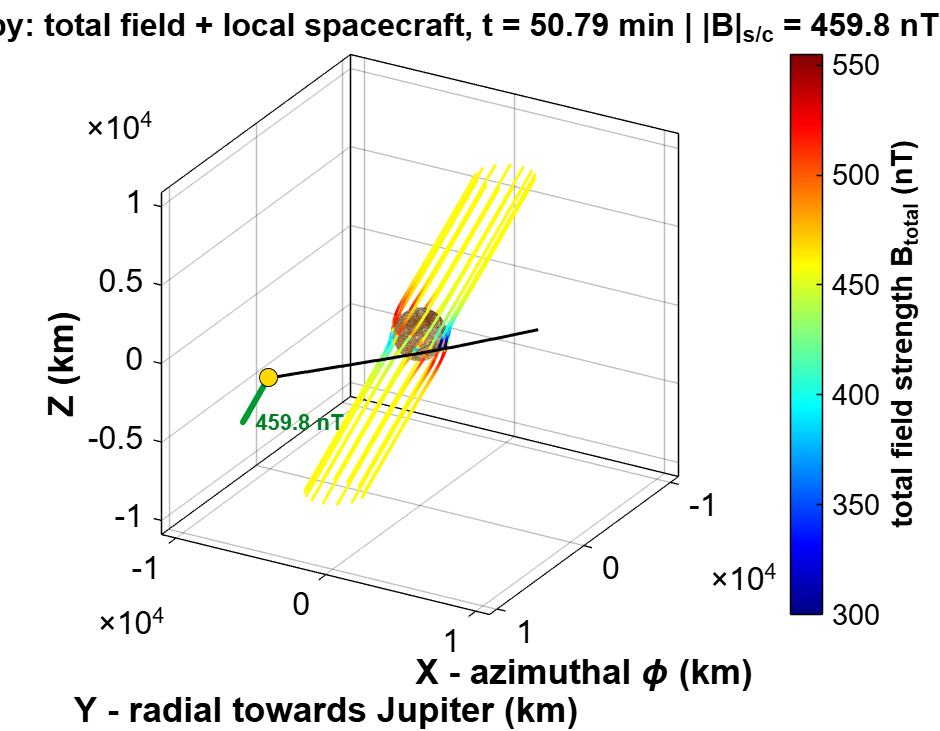


Bprim_x_amp = amp_x_fit;
Bprim_y_amp = amp_y_fit;
 
[~, i_min] = min(R_traj);
t_CA = traj_t(i_min) / 60; % in minutes
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
 
% create spatial grid (used for streamline background field, same as before)
 
num_points = 70;
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));
 
R = sqrt(X.^2 + Y.^2 + Z.^2);
mask = R >= r_m;
 
% down-sample the trajectory to a manageable number of animation frames
num_frames = min(120, length(traj_t));
frame_idx = round(linspace(1, length(traj_t), num_frames));
 
 
% storage for the actual sampled B values along the trajectory
t_series = traj_t(frame_idx);
Bmeas_series = B_meas(frame_idx, :);
Bx_series = zeros(size(frame_idx));
By_series = zeros(size(frame_idx));
Bz_series = zeros(size(frame_idx));
Bmag_series = zeros(size(frame_idx));
 
fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% load and prep image texture
planetImage = imread('europaimage.jpg');
shiftAmount = round(size(planetImage,2) * 1); % adjust to hide seam for current view
shiftedImage = circshift(planetImage, shiftAmount, 2);
[sx, sy, sz] = sphere(200);
 

% animation loop, one frame per sampled trajectory point
for fi = 1:length(frame_idx)
 
    k = frame_idx(fi);
    t = traj_t(k);              % seconds since encounter start
    sc_pos = traj_pos(k, :);    % current spacecraft position [x y z] (km)
 
    r_dot_e0x = X;
    r_dot_e0y = Y;
 
    % complex secondary field: x-driven (using complex response factor M_complex)
    coefx_c = -(M_complex * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t + phi0 + phi_x_offset)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .* X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .* Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .* Z);
 
    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(M_complex * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t + phi0 + phi_y_offset)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3 * r_dot_e0y .* X);
    Bsecy_y = coefy_c .* (3 * r_dot_e0y .* Y - R.^2);
    Bsecy_z = coefy_c .* (3 * r_dot_e0y .* Z);
 
    % complex primary background field (phi0 shifts this to the real
    % Jovian phase at the start of the encounter)
    Bprim_c_x = Bprim_x_amp * exp(-1i*(omega*t + phi0 + phi_x_offset));
    Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t + phi0 + phi_y_offset));
    Bprim_c_z = Bprim_z_amp;
 
    % superimpose total fields and take real components
    Bx = real(Bsecx_x + Bsecy_x + Bprim_c_x);
    By = real(Bsecx_y + Bsecy_y + Bprim_c_y);
    Bz = real(Bsecx_z + Bsecy_z + Bprim_c_z);
 
    % zero interior field matrix
    Bx(~mask) = 0;
    By(~mask) = 0;
    Bz(~mask) = 0;
 
    % total field magnitude
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);
 
    % sample the field at the spacecraft's position analytically (same formula
    % as the grid, but evaluated as a single point) works everywhere
    % along the real trajectory, even where it leaves the visualization grid
    xs = sc_pos(1); ys = sc_pos(2); zs = sc_pos(3);
    Rs = sqrt(xs^2 + ys^2 + zs^2);
 
    if Rs < r_m
        % inside Europa
        Bx_sc = 0; By_sc = 0; Bz_sc = 0;
    else
        coefx_c_s = -(M_complex * Bprim_x_amp * r_m^3) * exp(-1i*(omega*t + phi0 + phi_x_offset)) / (2 * Rs^5);
        Bsecx_x_s = coefx_c_s * (3 * xs * xs - Rs^2);
        Bsecx_y_s = coefx_c_s * (3 * xs * ys);
        Bsecx_z_s = coefx_c_s * (3 * xs * zs);
 
        coefy_c_s = -(M_complex * Bprim_y_amp * r_m^3) * exp(-1i*(omega*t + phi0 + phi_y_offset)) / (2 * Rs^5);
        Bsecy_x_s = coefy_c_s * (3 * ys * xs);
        Bsecy_y_s = coefy_c_s * (3 * ys * ys - Rs^2);
        Bsecy_z_s = coefy_c_s * (3 * ys * zs);
 
        Bprim_c_x_s = Bprim_x_amp * exp(-1i*(omega*t + phi0 + phi_x_offset));
        Bprim_c_y_s = Bprim_y_amp * exp(-1i*(omega*t + phi0 + phi_y_offset));
        Bprim_c_z_s = Bprim_z_amp;
 
        Bx_sc = real(Bsecx_x_s + Bsecy_x_s + Bprim_c_x_s);
        By_sc = real(Bsecx_y_s + Bsecy_y_s + Bprim_c_y_s);
        Bz_sc = real(Bsecx_z_s + Bsecy_z_s + Bprim_c_z_s);
    end
 
    % log the actual numeric values
    Bx_series(fi) = Bx_sc;
    By_series(fi) = By_sc;
    Bz_series(fi) = Bz_sc;
    Bmag_series(fi) = norm([Bx_sc, By_sc, Bz_sc]);
 
    % dynamic equator tracking from total primary field direction
    Bx_prim_now = real(Bprim_c_x);
    By_prim_now = real(Bprim_c_y);
    Bz_prim_now = real(Bprim_c_z);
 
 
    % seeds
    m_real = [Bx_prim_now; By_prim_now; Bz_prim_now];
    m_hat = m_real / norm(m_real);
 
    v1 = cross(m_hat, [0; 0; 1]);
    if norm(v1) < 1e-6
        v1 = cross(m_hat, [1; 0; 0]);
    end
    v1 = v1 / norm(v1);
    v2 = cross(m_hat, v1);
    v2 = v2 / norm(v2);
 
    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    radii_layers = 1.1 * r_m;
 
    total_seeds = length(radii_layers) * num_seeds_per_ring;
    seed_X = zeros(1, total_seeds);
    seed_Y = zeros(1, total_seeds);
    seed_Z = zeros(1, total_seeds);
 
    idx = 1;
    for r_seed = radii_layers
        for kk = 1:length(theta)
            pt = r_seed * (cos(theta(kk))*v1 + sin(theta(kk))*v2);
            seed_X(idx) = pt(1);
            seed_Y(idx) = pt(2);
            seed_Z(idx) = pt(3);
            idx = idx + 1;
        end
    end
 
    clf;
    set(gcf, 'Color', 'w');
 
    % draw solid Europa sphere
 
    h = surf(sx * r_m, sy * r_m, sz * r_m, ...
        'FaceColor', 'texturemap', ...
        'CData', flipud(shiftedImage), ...
        'EdgeColor', 'none', ...
        'FaceLighting', 'gouraud');
    hold on;
    axis equal;
 
    set(h, 'FaceLighting', 'gouraud', 'AmbientStrength', 0.4, 'SpecularStrength', 0.1);
 
    verts_forward = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts_backward = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));
 
    for kk = 1:num_seeds_per_ring
        v_f = verts_forward{kk};
        v_b = verts_backward{kk};
 
        if isempty(v_f) && isempty(v_b)
            continue;
        elseif isempty(v_f)
            v = v_b;
        elseif isempty(v_b)
            v = v_f;
        else
            v = [flipud(v_b); v_f];
        end
 
        line_colors = interp3(X, Y, Z, B_mag, v(:,1), v(:,2), v(:,3));
 
        surf_x = [v(:,1)'; v(:,1)'];
        surf_y = [v(:,2)'; v(:,2)'];
        surf_z = [v(:,3)'; v(:,3)'];
        surf_c = [line_colors'; line_colors'];
 
        surface(surf_x, surf_y, surf_z, surf_c, ...
                'FaceColor', 'none', ...
                'EdgeColor', 'interp', ...
                'LineWidth', 1.4);
    end
 
    % spacecraft marker, trailing path, local B vector arrow
    plot3(traj_pos(1:k,1), traj_pos(1:k,2), traj_pos(1:k,3), ...
          'k-', 'LineWidth', 1.5);
    plot3(sc_pos(1), sc_pos(2), sc_pos(3), 'o', ...
          'MarkerFaceColor', [1 0.85 0], 'MarkerEdgeColor', 'k', 'MarkerSize', 9);
 
    Bsc_norm = norm([Bx_sc, By_sc, Bz_sc]);
    if Bsc_norm > 1e-3
        arrow_scale = (2.2 * r_m) / Bsc_norm;
        quiver3(sc_pos(1), sc_pos(2), sc_pos(3), ...
                Bx_sc*arrow_scale, By_sc*arrow_scale, Bz_sc*arrow_scale, ...
                'Color', [0 0.6 0.2], 'LineWidth', 3, 'MaxHeadSize', 0.6, 'AutoScale', 'off');
        tip = sc_pos + [Bx_sc, By_sc, Bz_sc] * arrow_scale;
        text(tip(1), tip(2), tip(3), sprintf('  %.1f nT', Bsc_norm), ...
            'Color', [0 0.5 0.15], 'FontWeight', 'bold', 'FontSize', 11);
    end
 
    colormap(jet);
    c = colorbar;
    ylabel(c, 'total field strength B_{total} (nT)', 'FontWeight', 'bold', 'Color', 'k');
    c.Color = 'k';
 
    clim([300, 555]);
 
    axis equal; grid on; box on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
 
    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'FontSize', 16, 'ZColor', 'k', 'Color', 'w');
    xlabel('X - azimuthal \phi (km)', 'FontWeight', 'bold');
    ylabel('Y - radial towards Jupiter (km)', 'FontWeight', 'bold');
    zlabel('Z (km)', 'FontWeight', 'bold');
 
    view([120 25]);
 
    title(sprintf('%s flyby: total field + local spacecraft, t = %.2f min | |B|_{s/c} = %.1f nT', ...
        strrep(flyby_id, '_', '\_'), t/60, Bsc_norm), ...
        'Color', 'k', 'FontSize', 16, 'FontWeight', 'bold');
 
    drawnow;
    pause(0.04);
end

## stackplots

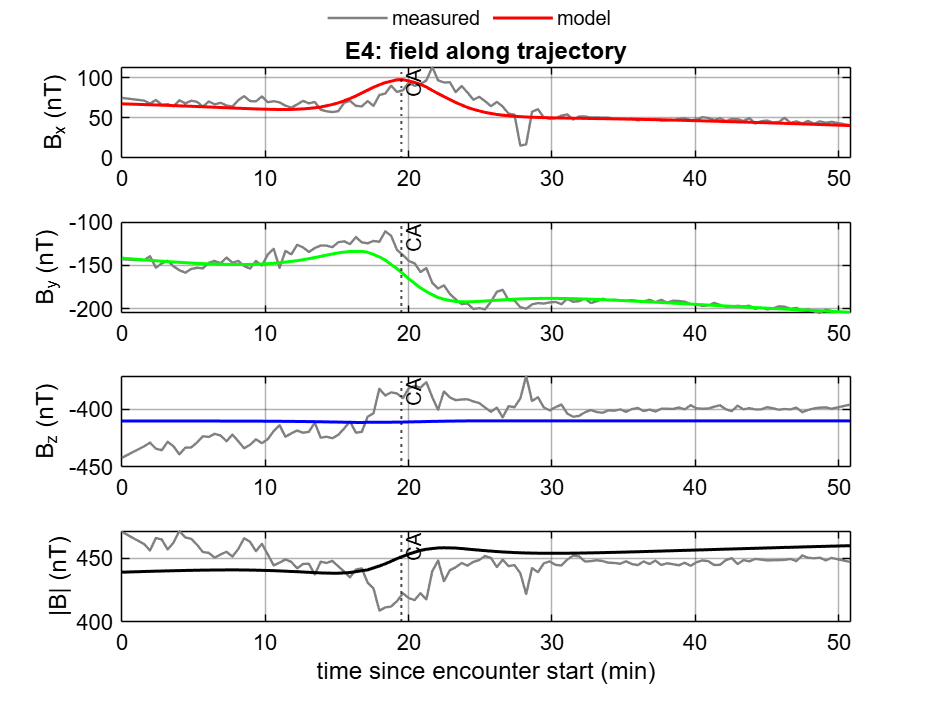

figure('Color', 'w', 'Position', [150, 150, 800, 600]);
 
subplot(4,1,1);
h1 = plot(t_series/60, Bmeas_series(:,1), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
h2 = plot(t_series/60, Bx_series, 'r-', 'LineWidth', 1.5);
ylabel('B_x (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
title(sprintf('%s: field along trajectory', flyby_id), 'Interpreter', 'none', 'Color', 'k');
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,2);
plot(t_series/60, Bmeas_series(:,2), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, By_series, 'g-', 'LineWidth', 1.5);
ylabel('B_y (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,3);
plot(t_series/60, Bmeas_series(:,3), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, Bz_series, 'b-', 'LineWidth', 1.5);
ylabel('B_z (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,4);
plot(t_series/60, Bmeas_series(:,4), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, Bmag_series, 'k-', 'LineWidth', 1.5);
ylabel('|B| (nT)', 'Color', 'k'); xlabel('time since encounter start (min)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
lgd = legend([h1 h2], {'measured', 'model'}, 'Orientation', 'horizontal', 'TextColor', 'k');
lgd.Position = [0.4, 0.96, 0.2, 0.03];
lgd.Box = 'off';
 
xlims = [0, max(traj_t)/60];   % full measured time range, in minutes
 
subplot(4,1,1); xlim(xlims);
subplot(4,1,2); xlim(xlims);
subplot(4,1,3); xlim(xlims);
subplot(4,1,4); xlim(xlims);

 
% print raw numbers
fprintf('\n%-10s %-10s %-10s %-10s %-10s\n', 't (min)', 'Bx', 'By', 'Bz', '|B|');


t (min)    Bx         By         Bz         |B|       


for fi = 1:5:length(t_series)
    fprintf('%-10.2f %-10.2f %-10.2f %-10.2f %-10.2f\n', ...
        t_series(fi)/60, Bx_series(fi), By_series(fi), Bz_series(fi), Bmag_series(fi));
end

0.00       67.29      -141.65    -410.03    439.00    
3.19       65.38      -145.65    -410.06    440.04    
5.24       63.98      -147.63    -410.09    440.52    
7.30       62.43      -148.84    -410.15    440.77    
9.35       60.99      -148.69    -410.21    440.57    
11.41      60.27      -146.21    -410.38    439.79    
13.46      62.37      -140.98    -410.67    438.65    
15.51      71.10      -134.71    -411.13    438.44    
17.55      87.84      -137.41    -411.15    442.31    
19.60      97.21      -159.40    -411.00    451.42    
21.65      83.94      -183.84    -410.44    457.50    
23.69      65.87      -191.99    -410.06    457.55    
25.74      55.36      -190.64    -409.96    455.49    
27.79      51.39      -188.67    -409.95    454.20    
29.84      50.01      -188.04    -409.96    453.79    
31.89      49.36      -188.59    -409.99    453.97    
33.93      48.77      -189.82    -409.99    454.42    
35.98      48.09      -191.40    -409.99    455.02    
38.03     

## residual plot and errors

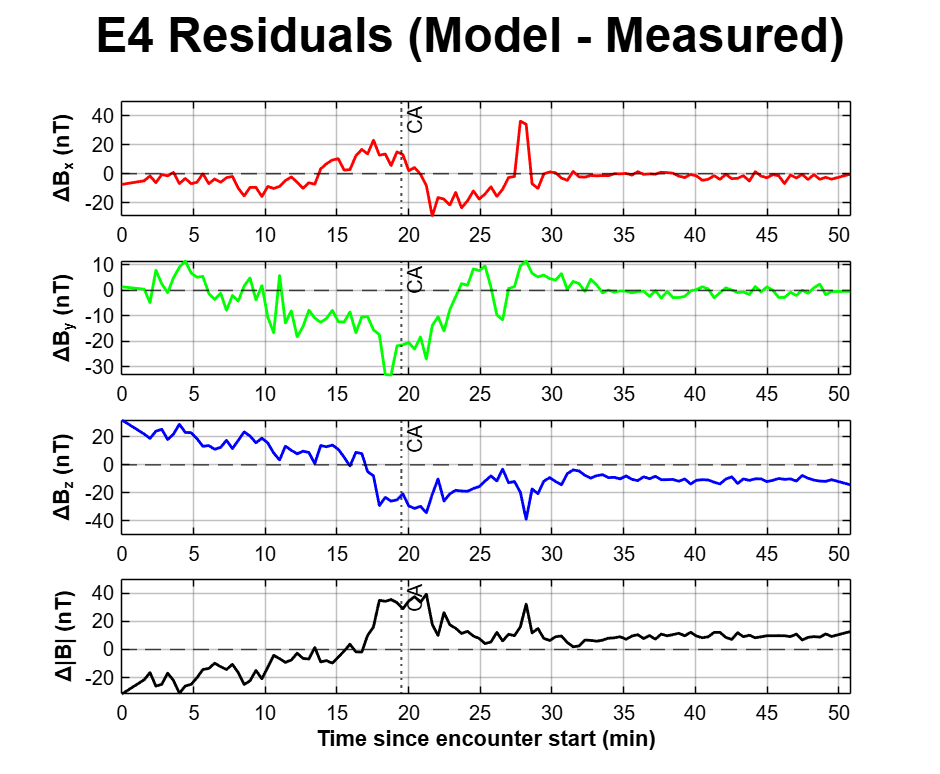

% residual plot and errors
% residual plot (model-measured)

% 1. clean data and handle NaNs
valid_mask = ~any(isnan(Bmeas_series), 2);

t_v     = t_series(valid_mask) / 60; % time in minutes
Bmeas_v = Bmeas_series(valid_mask, :);
Bmod_v  = [Bx_series(valid_mask)', By_series(valid_mask)', ...
    Bz_series(valid_mask)', Bmag_series(valid_mask)'];

% 2. calculate residuals (model - measured) in nT
res = Bmod_v - Bmeas_v; % [Bx_res, By_res, Bz_res, Bmag_res]

% 3. create residual plot figure
fig_res = figure('Color', 'w', 'Position', [200, 150, 850, 700]);

% component Bx residual
subplot(4,1,1);
plot(t_v, res(:,1), 'r-', 'LineWidth', 1.4); hold on;
yline(0, 'k--', 'LineWidth', 0.8);
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
ylabel('\DeltaB_x (nT)', 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(gca, 'Color', 'w', 'FontSize', 10, 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.2 0.2 0.2], 'GridAlpha', 0.3);

% component By residual
subplot(4,1,2);
plot(t_v, res(:,2), 'g-', 'LineWidth', 1.4); hold on;
yline(0, 'k--', 'LineWidth', 0.8);
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
ylabel('\DeltaB_y (nT)', 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(gca, 'Color', 'w', 'FontSize', 10, 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.2 0.2 0.2], 'GridAlpha', 0.3);

% component Bz residual
subplot(4,1,3);
plot(t_v, res(:,3), 'b-', 'LineWidth', 1.4); hold on;
yline(0, 'k--', 'LineWidth', 0.8);
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
ylabel('\DeltaB_z (nT)', 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(gca, 'Color', 'w', 'FontSize', 10, 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.2 0.2 0.2], 'GridAlpha', 0.3);

% magnitude |B| residual
subplot(4,1,4);
plot(t_v, res(:,4), 'k-', 'LineWidth', 1.4); hold on;
yline(0, 'k--', 'LineWidth', 0.8);
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
ylabel('\Delta|B| (nT)', 'FontWeight', 'bold', 'Color', 'k');
xlabel('Time since encounter start (min)', 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(gca, 'Color', 'w', 'FontSize', 10, 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.2 0.2 0.2], 'GridAlpha', 0.3);

% match x-limits across all subplots
res_xlims = [0, max(t_v)];
subplot(4,1,1); xlim(res_xlims);
subplot(4,1,2); xlim(res_xlims);
subplot(4,1,3); xlim(res_xlims);
subplot(4,1,4); xlim(res_xlims);


% overall figure title
sgtitle(sprintf('%s Residuals (Model - Measured)', flyby_id), ...
    'Interpreter', 'none', 'FontSize', 24, 'FontWeight', 'bold', 'Color', 'k');


% percent differences

% mean absolute percentage error (MAPE) for total magnitude |B|
% (avoids dividing by zero by filtering out tiny values)
valid_b_idx = abs(Bmeas_v(:,4)) > 1;
mape_mag = mean(abs(res(valid_b_idx, 4) ./ Bmeas_v(valid_b_idx, 4))) * 100;

% normalized RMSE relative to the total range of measured |B| (%)
rmse_mag = sqrt(mean(res(:,4).^2));  % RMS error of |B| in nT
nrmse_mag = (rmse_mag / (max(Bmeas_v(:,4)) - min(Bmeas_v(:,4)))) * 100;

fprintf('  MODEL FIT METRICS FOR %s\n', flyby_id);

  MODEL FIT METRICS FOR E4


fprintf('  inputs: sigma = %.2f S/m | h_ocean = %.0f km | d_ice = %.0f km\n', ...
    sigma_ocean, h_ocean, d_ice);

  inputs: sigma = 2.75 S/m | h_ocean = 150 km | d_ice = 29 km


fprintf('\n========================================================\n');

fprintf('  mean absolute percent error (|B|):  %6.2f %%\n', mape_mag);

  mean absolute percent error (|B|):    2.95 %


fprintf('  normalized RMS error (|B|):          %6.2f %%\n', nrmse_mag);

  normalized RMS error (|B|):           25.25 %


fprintf('  RMS Error (|B|):                     %6.2f nT\n', rmse_mag);

  RMS Error (|B|):                      15.73 nT


fprintf('  theoretical response amplitude (A):  %6.4f\n', A);

  theoretical response amplitude (A):  0.9453


## parameter sensivity graphs 

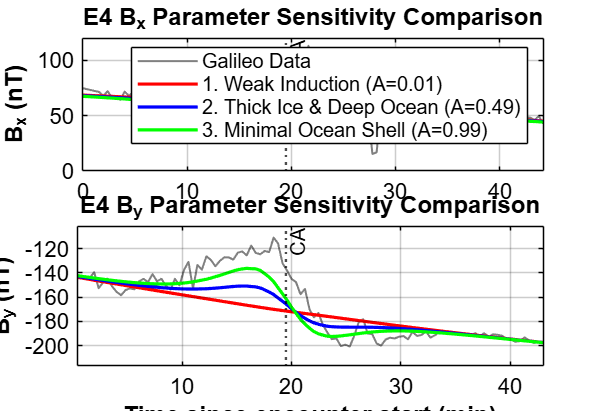


% define 3 extreme scenarios: [sigma (S/m), h_ocean (km), d_ice (km)]
scenarios = {
    '1. Weak Induction',  [0.001,   150,  29];
    '2. Thick Ice & Deep Ocean',       [2.75,  1000, 300];
    '3. Minimal Ocean Shell',          [2.75,  15, 29]
};
 
num_sc = size(scenarios, 1);
 
% ensure valid_mask exists
if ~exist('valid_mask', 'var') || isempty(valid_mask)
    if exist('Bmeas_v', 'var')
        valid_mask = true(size(Bmeas_v, 1), 1);
    elseif exist('t_series', 'var')
        valid_mask = true(size(t_series));
    end
end
 
% ensure t_v exists (time in minutes relative to flyby start)
if ~exist('t_v', 'var')
    if exist('t_series', 'var')
        t_v = (t_series(valid_mask) - t_series(1)) / 60; % convert seconds to minutes if needed
    elseif exist('t_min', 'var')
        t_v = t_min;
    end
end
 
% define window around closest approach (t_CA)
ca_window_min = 25;
ca_mask = (t_v >= (t_CA - ca_window_min)) & (t_v <= (t_CA + ca_window_min));
 
t_zoom      = t_v(ca_mask);
 
% extract measured Bx and By components for the zoomed window
if exist('Bmeas_v', 'var')
    Bmeas_zoom = Bmeas_v(ca_mask, 1:2); % Column 1 = Bx, Column 2 = By
else
    Bmeas_zoom = Bmeas(ca_mask, 1:2);
end
 
% extract trajectory time in seconds and positions for the window
if exist('t_series_v', 'var')
    t_zoom_sec = t_series_v(ca_mask);
else
    t_series_v = t_series(valid_mask);
    t_zoom_sec = t_series_v(ca_mask);
end
 
if exist('p_v', 'var')
    p_zoom = p_v(ca_mask, :);
else
    p_all  = traj_pos(frame_idx, :);
    p_v    = p_all(valid_mask, :);
    p_zoom = p_v(ca_mask, :);
end
 
% storage matrices for component sensitivity and percent error

B_sens_comp_zoom  = zeros(sum(ca_mask), num_sc, 2);
pe_sens_comp_zoom = zeros(sum(ca_mask), num_sc, 2);
A_sens            = zeros(1, num_sc);
 
% loop through each extreme scenario
for s = 1:num_sc
    s_sigma = scenarios{s, 2}(1);
    s_h     = scenarios{s, 2}(2);
    s_d     = scenarios{s, 2}(3);
 
    [s_A, ~, s_M] = calc_europa_induction(s_sigma, s_h, s_d, r_m, synodic_period);
    A_sens(s) = s_A;
 
    for idx_i = 1:length(t_zoom)
        t_now = t_zoom_sec(idx_i);
        sc_p  = p_zoom(idx_i, :);
        Rs_i  = norm(sc_p);
 
        if Rs_i >= r_m
            cx = -(s_M * Bprim_x_amp * r_m^3) * exp(-1i*(omega*t_now + phi0 + phi_x_offset)) / (2 * Rs_i^5);
            cy = -(s_M * Bprim_y_amp * r_m^3) * exp(-1i*(omega*t_now + phi0 + phi_y_offset)) / (2 * Rs_i^5);
 
            px = Bprim_x_amp * exp(-1i*(omega*t_now + phi0 + phi_x_offset));
            py = Bprim_y_amp * exp(-1i*(omega*t_now + phi0 + phi_y_offset));
 
            bx = real(cx*(3*sc_p(1)^2 - Rs_i^2) + cy*(3*sc_p(2)*sc_p(1)) + px);
            by = real(cx*(3*sc_p(1)*sc_p(2)) + cy*(3*sc_p(2)^2 - Rs_i^2) + py);
 
            B_sens_comp_zoom(idx_i, s, 1) = bx; % store Bx
            B_sens_comp_zoom(idx_i, s, 2) = by; % store By
        end
    end
 
    % relative percent error against Galileo Bx and By components
    pe_sens_comp_zoom(:, s, 1) = abs(B_sens_comp_zoom(:, s, 1) - Bmeas_zoom(:, 1)) ./ abs(Bmeas_zoom(:, 1)) * 100;
    pe_sens_comp_zoom(:, s, 2) = abs(B_sens_comp_zoom(:, s, 2) - Bmeas_zoom(:, 2)) ./ abs(Bmeas_zoom(:, 2)) * 100;
end
 
colors = {'r-', 'b-', 'g-'};

exact_data_limits = [min(t_zoom), max(t_zoom)];
 
 
% FIGURE 1: Bx and By stackplot
 
fig_field = figure('Color', 'w', 'Position', [100, 100, 950, 650]);
 
% subplot 1: Bx component
ax1 = subplot(2, 1, 1);
plot(t_zoom, Bmeas_zoom(:, 1), 'Color', [0.5 0.5 0.5]', 'LineWidth', 1.0, 'DisplayName', 'Galileo Data'); hold on;
for s = 1:num_sc
    plot(t_zoom, B_sens_comp_zoom(:, s, 1), colors{s}, 'LineWidth', 1.6, ...
        'DisplayName', sprintf('%s (A=%.2f)', scenarios{s,1}, A_sens(s)));
end
xline(t_CA, 'k:', 'CA', 'LineWidth', 1.2, 'Color', 'k', 'HandleVisibility', 'off');
ylabel('B_x (nT)', 'FontWeight', 'bold', 'Color', 'k');
title(sprintf('%s B_x Parameter Sensitivity Comparison', flyby_id), ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(ax1, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.2, 'FontSize', 11, 'Layer', 'top');
legend(ax1, 'Location', 'northeast', 'Color', 'w', 'EdgeColor', 'k', 'TextColor', 'k');
 
% subplot 2: By component
ax2 = subplot(2, 1, 2);
plot(t_zoom, Bmeas_zoom(:, 2), 'Color', [0.5 0.5 0.5]', 'LineWidth', 1.0, 'DisplayName', 'Galileo Data'); hold on;
for s = 1:num_sc
    plot(t_zoom, B_sens_comp_zoom(:, s, 2), colors{s}, 'LineWidth', 1.6);
end
xline(t_CA, 'k:', 'CA', 'LineWidth', 1.2, 'Color', 'k', 'HandleVisibility', 'off');
xlabel('Time since encounter start (min)', 'FontWeight', 'bold', 'Color', 'k');
ylabel('B_y (nT)', 'FontWeight', 'bold', 'Color', 'k');
title(sprintf('%s B_y Parameter Sensitivity Comparison', flyby_id), ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(ax2, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.2, 'FontSize', 11, 'Layer', 'top');
 
% align subplot horizontal axes
pos1 = get(ax1, 'Position');
pos2 = get(ax2, 'Position');
pos2(3) = pos1(3);
set(ax2, 'Position', pos2);
xlim(ax1, exact_data_limits);
xlim(ax2, exact_data_limits);

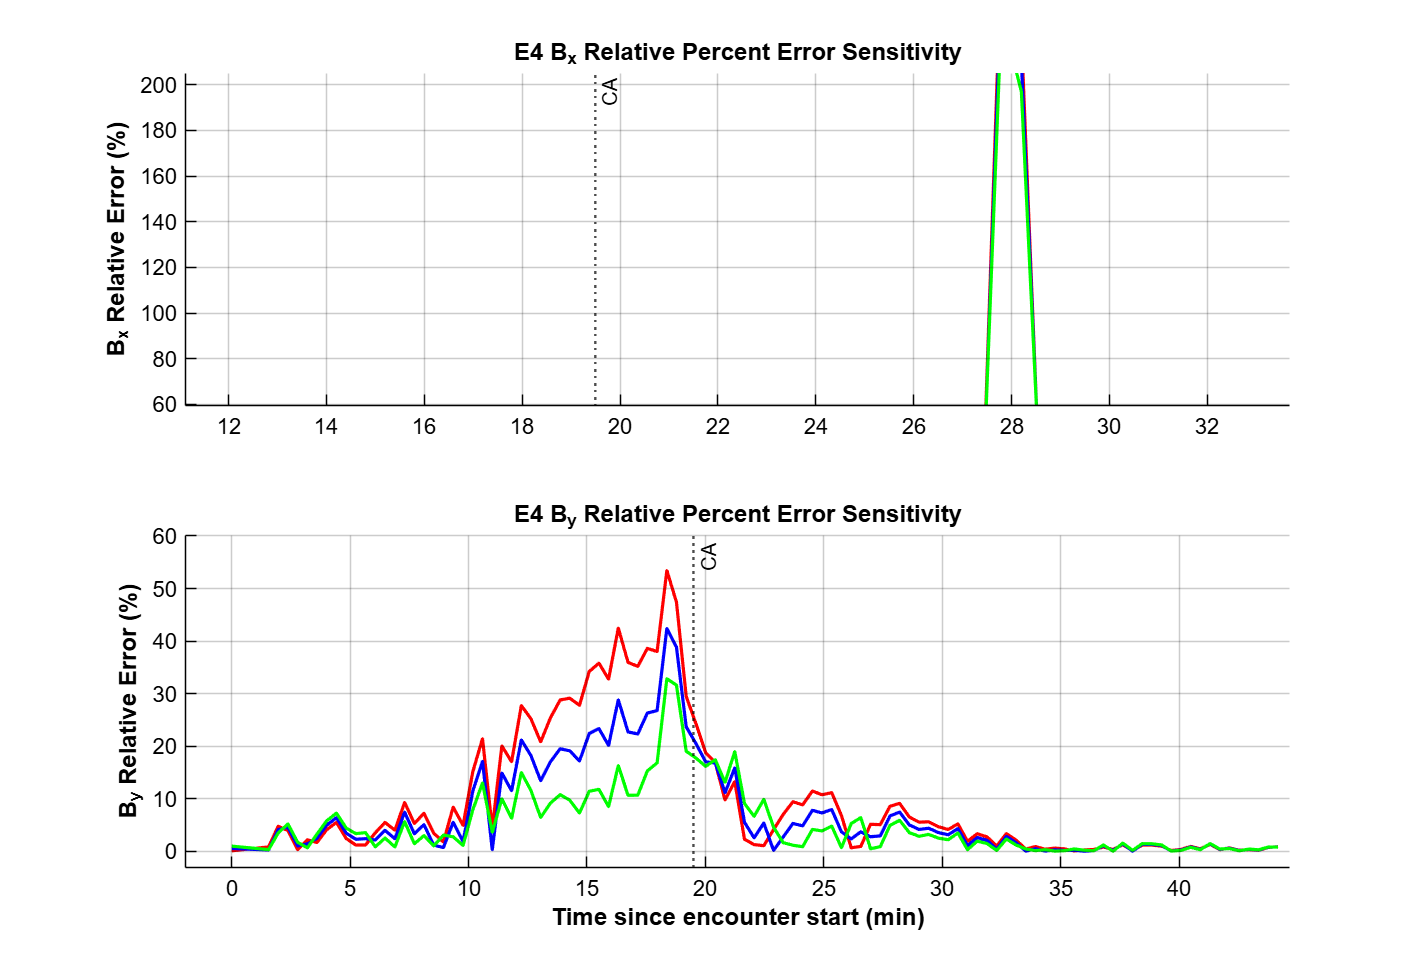

 
 
% FIGURE 2: Bx and By percent error Stackplot
 
fig_pe = figure('Color', 'w', 'Position', [1050, 100, 950, 650]);
 
% subplot 1: Bx percent error
ax3 = subplot(2, 1, 1);
hold on;
for s = 1:num_sc
    plot(t_zoom, pe_sens_comp_zoom(:, s, 1), colors{s}, 'LineWidth', 1.6, ...
        'DisplayName', sprintf('%s (A=%.2f)', scenarios{s,1}, A_sens(s)));
end
xline(t_CA, 'k:', 'CA', 'LineWidth', 1.2, 'Color', 'k', 'HandleVisibility', 'off');
ylabel('B_x Relative Error (%)', 'FontWeight', 'bold', 'Color', 'k');
title(sprintf('%s B_x Relative Percent Error Sensitivity', flyby_id), ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(ax3, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.2, 'FontSize', 11, 'Layer', 'top');
 
 
% subplot 2: By percent error
ax4 = subplot(2, 1, 2);
hold on;
for s = 1:num_sc
    plot(t_zoom, pe_sens_comp_zoom(:, s, 2), colors{s}, 'LineWidth', 1.6);
end
xline(t_CA, 'k:', 'CA', 'LineWidth', 1.2, 'Color', 'k', 'HandleVisibility', 'off');
xlabel('Time since encounter start (min)', 'FontWeight', 'bold', 'Color', 'k');
ylabel('B_y Relative Error (%)', 'FontWeight', 'bold', 'Color', 'k');
title(sprintf('%s B_y Relative Percent Error Sensitivity', flyby_id), ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
grid on;
set(ax4, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.2, 'FontSize', 11, 'Layer', 'top');
 
% align subplot horizontal axes
pos3 = get(ax3, 'Position');
pos4 = get(ax4, 'Position');
pos4(3) = pos3(3);
set(ax4, 'Position', pos4);
xlim(ax3, exact_data_limits);
xlim(ax4, exact_data_limits);

## functions


% local functions
 
function [traj_t, traj_pos, B_meas] = load_galileo_tab(filename)
% loads a PDS Galileo mag+trajectory .tab file in ephio coordinates
% from lbl file, columns are:
%   1   : spacecraft event time, ISO 8601
%   2-4 : BX, BY, BZ measured magnetic field (nT)
%   5   : |B| magnitude (nT)
%   6-8 : X, Y, Z spacecraft position in EUROPA RADII (RE = 1560 km)
 
 
% returns:
%   traj_t   : Nx1, seconds elapsed since the first row in the file
%   traj_pos : Nx3, [x y z] position in km (converted from Europa radii)
%   B_meas   : Nx4, [Bx By Bz Bmag] measured field in nT
 
RE = 1560; % Europa radius on lbl
 
raw = readlines(filename);
raw = raw(strlength(strtrim(raw)) > 0);
n = length(raw);
 
t_dt = NaT(n,1);
B_meas = zeros(n,4);
traj_pos = zeros(n,3);
 
for i = 1:n
    parts = strsplit(strtrim(raw(i)));
    t_dt(i) = datetime(parts{1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS');
    B_meas(i,:) = str2double(parts(2:5));           % Bx, By, Bz, |B|
    traj_pos(i,:) = str2double(parts(6:8)) * RE;
end
 
% missing-value handling
B_meas(B_meas > 999998) = NaN;
traj_pos(abs(traj_pos) > 999.98*RE) = NaN;
 
traj_t = seconds(t_dt - t_dt(1));
end
 
 
% this function is for inputting my own values
% to use it make a
% case in the switch block back to calling this function with my own
% CA_alt / v_sc / approach_dir values instead of load_galileo_tab()
 
function [traj_t, traj_pos] = make_synthetic_flyby(r_m, CA_alt, v_sc, approach_dir)
% builds a straight-line flyby trajectory as a placeholder, passing
% Europa at closest approach altitude CA_alt (km) with speed v_sc (km/s)
% along direction approach_dir
 
    b = r_m + CA_alt;                     % impact parameter (km)
    dir_travel = approach_dir / norm(approach_dir);
 
    perp = cross(dir_travel, [0 0 1]);
    if norm(perp) < 1e-6
        perp = cross(dir_travel, [1 0 0]);
    end
    perp = perp / norm(perp);
    ca_point = b * perp;                  % closest-approach point
 
    half_range = 3 * r_m;                 % extent of trajectory shown (km)
    n_pts = 200;
    s = linspace(-half_range, half_range, n_pts)';   % along-track distance
 
    traj_pos = ca_point + s * dir_travel;             % Nx3, km
    traj_t = s / v_sc;                                 % seconds
    traj_t = traj_t - traj_t(1);                       % re-zero to start at 0
end
 
function [A, phi, M] = calc_europa_induction(sigma, h, d, r_m, synodic_period)
% computes response factor M = A*exp(i*phi)
% using half-integer spherical Bessel functions (Zimmer et al. 2000).
 
mu0 = 4*pi*1e-7;                % permeability of free space (H/m)
omega = 2*pi / synodic_period;  % rad/s
 
r0 = r_m - d;                   % outer ocean radius (km)
r1 = r0 - h;                    % inner ocean boundary (km)
 
r0_m = r0 * 1e3;                % convert to meters for SI equation
r1_m = r1 * 1e3;
 
% wavenumber in conductor: k = (1 - i) / skin_depth
k = (1 - 1i) * sqrt(mu0 * sigma * omega / 2);
 
% half-integer spherical Bessel functions evaluated at z = k*r
J_12  = @(z) sqrt(2./(pi*z)) .* sin(z);
J_n12 = @(z) sqrt(2./(pi*z)) .* cos(z);
J_32  = @(z) sqrt(2./(pi*z)) .* (sin(z)./z - cos(z));
J_52  = @(z) sqrt(2./(pi*z)) .* ((3./z.^2 - 1).*sin(z) - 3*cos(z)./z);
J_n52 = @(z) sqrt(2./(pi*z)) .* ((3./z.^2 - 1).*cos(z) + 3*sin(z)./z);
 
z1 = k * r1_m;
z0 = k * r0_m;
 
% core boundary reflection ratio R (Eq. 6)
R_factor = (z1 .* J_n52(z1)) ./ (3 * J_32(z1) - z1 .* J_12(z1));
 
% complex response factor M = A * exp(i*phi) (Eq. 5)
M = -(r0 / r_m)^3 * (R_factor .* J_52(z0) - J_n52(z0)) ...
    / (R_factor .* J_12(z0) - J_n12(z0));
 
A = abs(M);
phi = angle(M); % phase lag in radians
end
 